%%%%%
%%% 5LIJ0 Embedded Control Systems
%%% Assignment 1
%%% Author: Jiaxuan Zhang
%%%%%


## Parameters

% Dual Rotary System Parameters
DR.Km = 4.4 * 1e-2;
DR.J1 = 3.75 * 1e-6; 
DR.J2 = 3.75 * 1e-6;
DR.b = 1 * 1e-5;
DR.k = 0.2656;
DR.d = 3.125 * 1e-5;
DR.nx = 5;
DR.nu = 1;

% DC Motor Speed Control System Parameters
DCM.K = 0.01;
DCM.J = 0.01;
DCM.b = 0.1;
DCM.R = 1;
DCM.L = 0.5;
DCM.nx = 3;
DCM.nu = 1;

% sampling time(s)
DR.h = 2e-3;
DCM.h = 2 * DR.h;
tau = 4e-4;


## State Space Model

% Dual Rotary System
DR_CS.A = [0, 0, 1, 0;
           0, 0, 0, 1;
           -DR.k / DR.J1, DR.k / DR.J1, - (DR.d + DR.b) / DR.J1, (DR.d + DR.b) / DR.J1;
           DR.k / DR.J2, -DR.k / DR.J2, (DR.d + DR.b) / DR.J2, - (DR.d + DR.b) / DR.J2];
DR_CS.B = [0;
           0;
           DR.Km / DR.J1;
           0];
DR_CS.C = [1 1 0 0];

% DC Motor Speed Control System
DCM_CS.A = [-DCM.b / DCM.J, DCM.K / DCM.J;
            -DCM.K / DCM.L, -DCM.R / DCM.L];
DCM_CS.B = [0;
            1 / DCM.L];
DCM_CS.C = [1 0];


### DR Control System

% continuous-time
DR_CS.sysc = ss(DR_CS.A, DR_CS.B, DR_CS.C, 0);

% to discrete
DR_CS.sysd = c2d(DR_CS.sysc, DR.h);
DR_CS.phi = DR_CS.sysd.a; 
DR_CS.Gamma = DR_CS.sysd.b; 
DR_CS.Cd = DR_CS.sysd.c;

% with delay
% DR_CS_aug.Gamma0 = inv(DR_CS.A) * (expm(DR_CS.A * (DR.h - tau)) - expm(DR_CS.A*0)) * DR_CS.B;
% DR_CS_aug.Gamma1 = inv(DR_CS.A) * (expm(DR_CS.A * DR.h) - expm(DR_CS.A * (DR.h-tau))) * DR_CS.B;
% simpilfied calculation
DR_CS_aug.Gamma0 = tau * DR_CS.B + 0.5 * DR_CS.A * (DR.h^2 - (DR.h - tau)^2) * DR_CS.B;
DR_CS_aug.Gamma1 = (DR.h - tau) * DR_CS.B + 0.5 * DR_CS.A * (DR.h - tau)^2 * DR_CS.B;

% sysd2 = c2d(DR_CS.sysc, DR.h - tau);
% 
% DR_CS_aug.Gamma0 = sysd2.b;
% DR_CS_aug.Gamma1 = DR_CS.Gamma - DR_CS_aug.Gamma0;

% augmentation
DR_CS_aug.phi= [DR_CS.phi DR_CS_aug.Gamma1; zeros(1,DR.nx)];
DR_CS_aug.Gamma= [DR_CS_aug.Gamma0; 1];
DR_CS_aug.C= [DR_CS.Cd 0];

% Desired closed-loop poles and pole placement
DR_CS_aug.alpha = [0.65 0.65 0.65 0.65 0.65];
% alternative [0.6 0.6 0.65 0.65 0.65]

% feedback vector
DR_CS_aug.K = -acker(DR_CS_aug.phi, DR_CS_aug.Gamma, DR_CS_aug.alpha);

% feedforward gain
temp = (eye(DR.nx) - DR_CS_aug.phi - DR_CS_aug.Gamma * DR_CS_aug.K) \ DR_CS_aug.Gamma;
DR_CS_aug.F = 1 / (DR_CS_aug.C * temp);
clear temp


% Simulink Simulation
assignment1_2022_Simulink_init_Dualrotary(tau, DR.h, DR_CS_aug.K, 2*DR_CS_aug.F)

Variables initialized for Dual rotary system in Simulink model


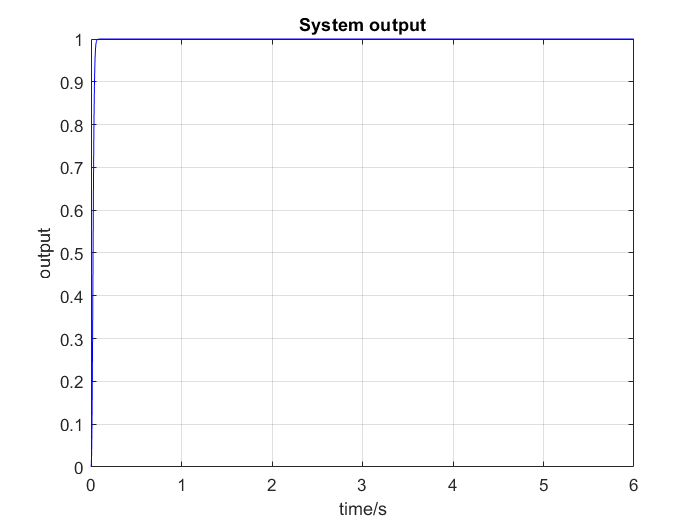

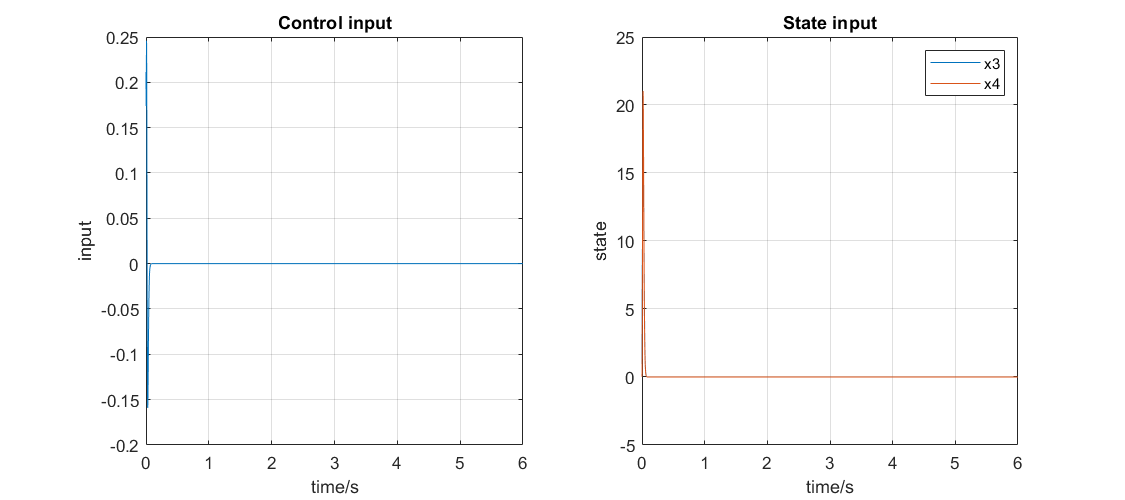



SC_plot(DR, DR_CS_aug, [0;0;0;0;0], "DR")

## DCM Control System

% continuous-time
DCM_CS.sysc = ss(DCM_CS.A, DCM_CS.B, DCM_CS.C, 0);

% to discrete
DCM_CS.sysd = c2d(DCM_CS.sysc, DCM.h);
DCM_CS.phi = DCM_CS.sysd.a; 
DCM_CS.Gamma = DCM_CS.sysd.b; 
DCM_CS.Cd = DCM_CS.sysd.c;

% with delay
DCM_CS_aug.Gamma0 = (DCM_CS.A) \ (expm(DCM_CS.A * (DCM.h-tau))-expm(DCM_CS.A * 0)) * DCM_CS.B;
DCM_CS_aug.Gamma1 = (DCM_CS.A) \ (expm(DCM_CS.A * DCM.h)-expm(DCM_CS.A * (DCM.h - tau))) * DCM_CS.B;

% augmentation
DCM_CS_aug.phi = [DCM_CS.phi DCM_CS_aug.Gamma1; zeros(1,DCM.nx)];
DCM_CS_aug.Gamma= [DCM_CS_aug.Gamma0; 1];
DCM_CS_aug.Cd = [DCM_CS.Cd 0];

% Desired closed-loop poles and pole placement
DCM_CS_aug.alpha = [0.98 0.98 0.98];
% alternative [0.984 0.984 0.984]

% feedback vector
DCM_CS_aug.K = -acker(DCM_CS_aug.phi, DCM_CS_aug.Gamma, DCM_CS_aug.alpha);

% feedforward gain
temp = (eye(DCM.nx) - DCM_CS_aug.phi - DCM_CS_aug.Gamma * DCM_CS_aug.K) \ DCM_CS_aug.Gamma;
DCM_CS_aug.F = 1 / (DCM_CS_aug.Cd * temp);

clear temp

% SC_plot(DCM, DCM_CS_aug, [0;0;0], "DCM")

% Simulink Simulation
assignment1_2022_Simulink_init_DCmotor(tau, DCM.h, DCM_CS_aug.K, DCM_CS_aug.F)

Variables initialized for DC motor system in Simulink model
